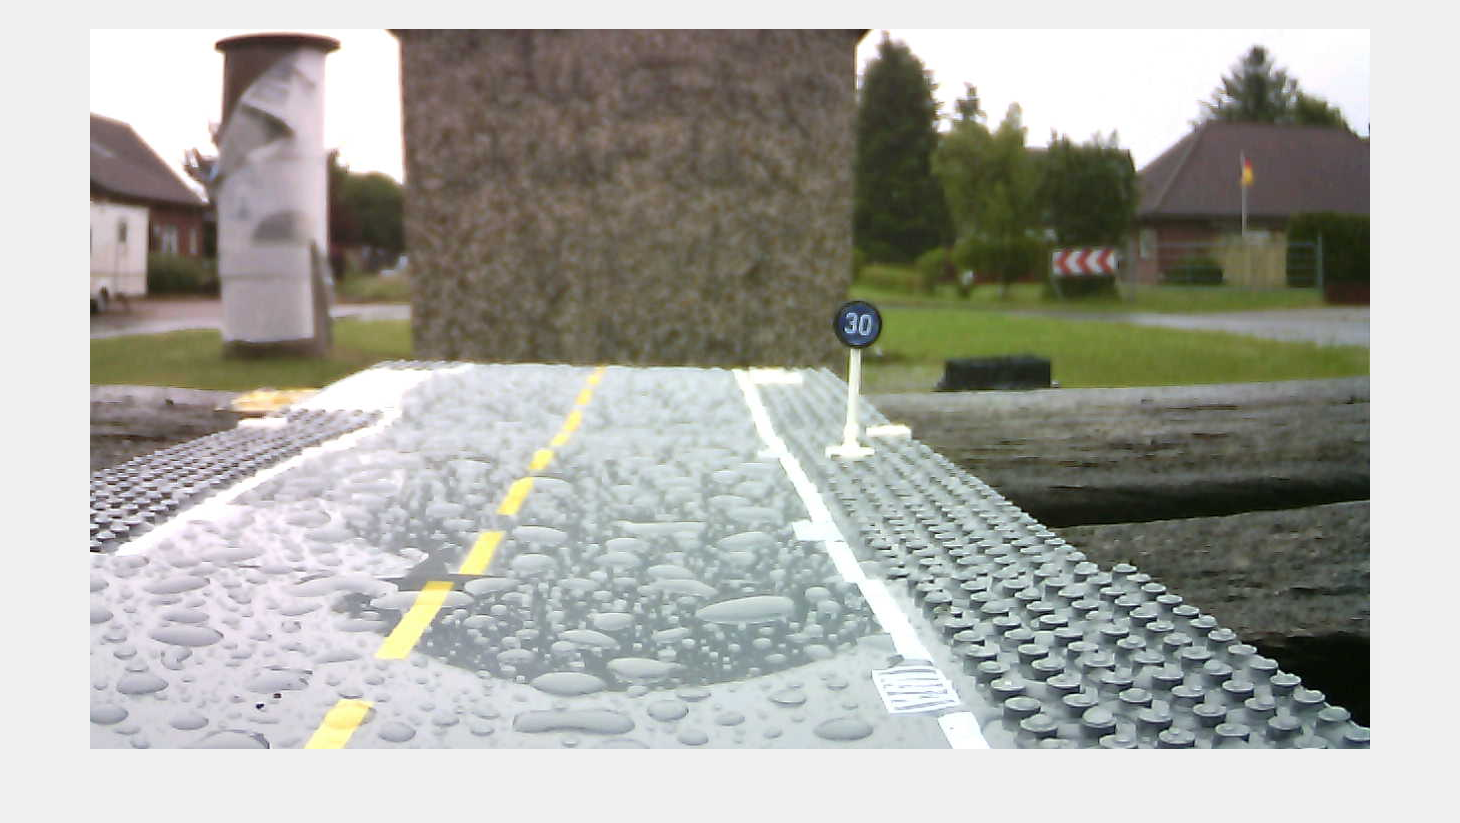

directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\1_Runde_Schilder\Geschwindigkeitsempfehlungen\Geschwindigkeitsempfehlung 30\Bushaltestelle";
cd(directory);      % Arbeitsverzeichnis setzen

I = imread("Geschwindigkeitsempfehlung_30-2025-06-05__1.jpg");
imshow(I);

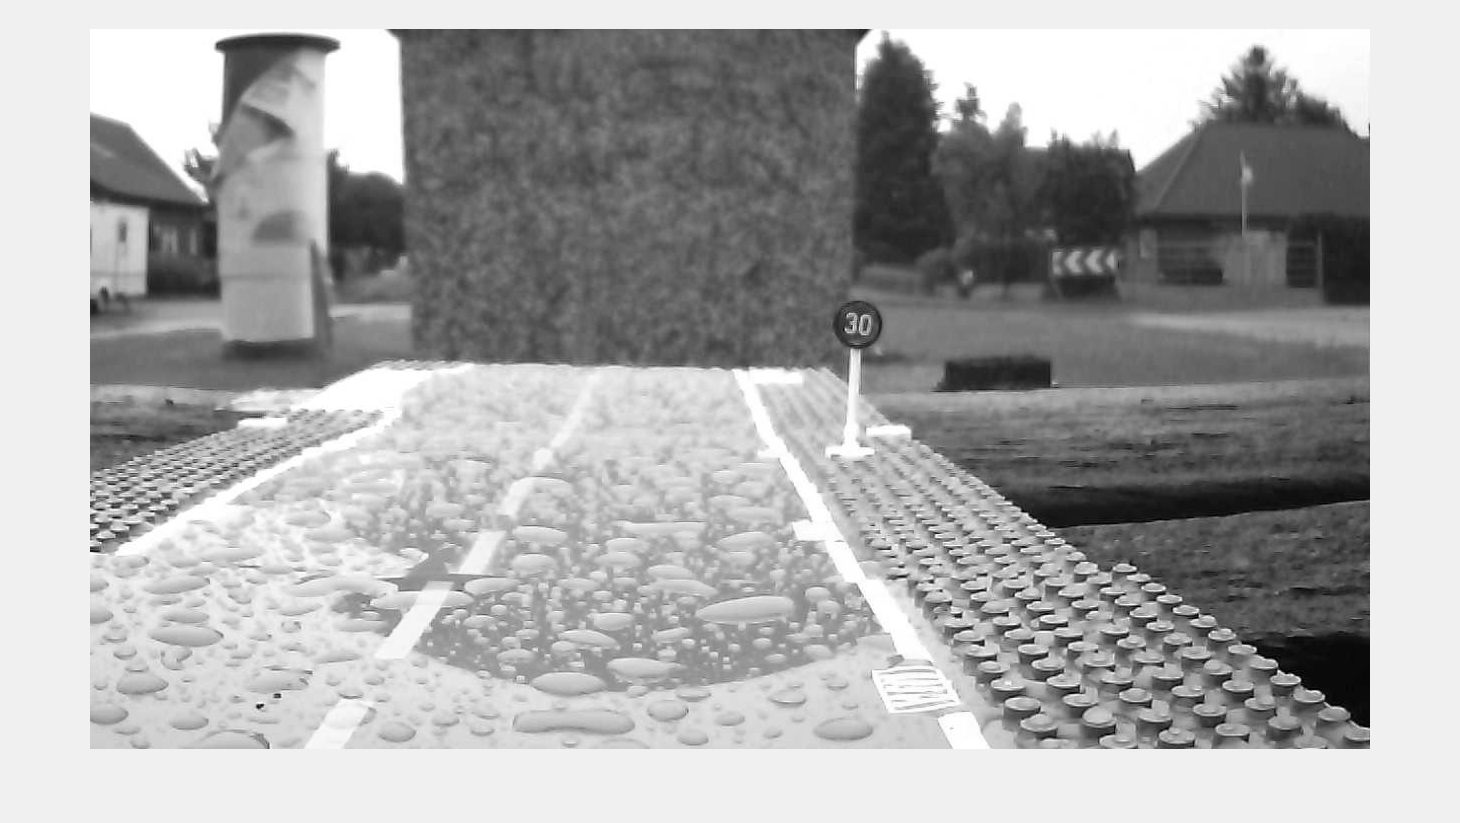

grayImage = rgb2gray(I);
imshow(grayImage);

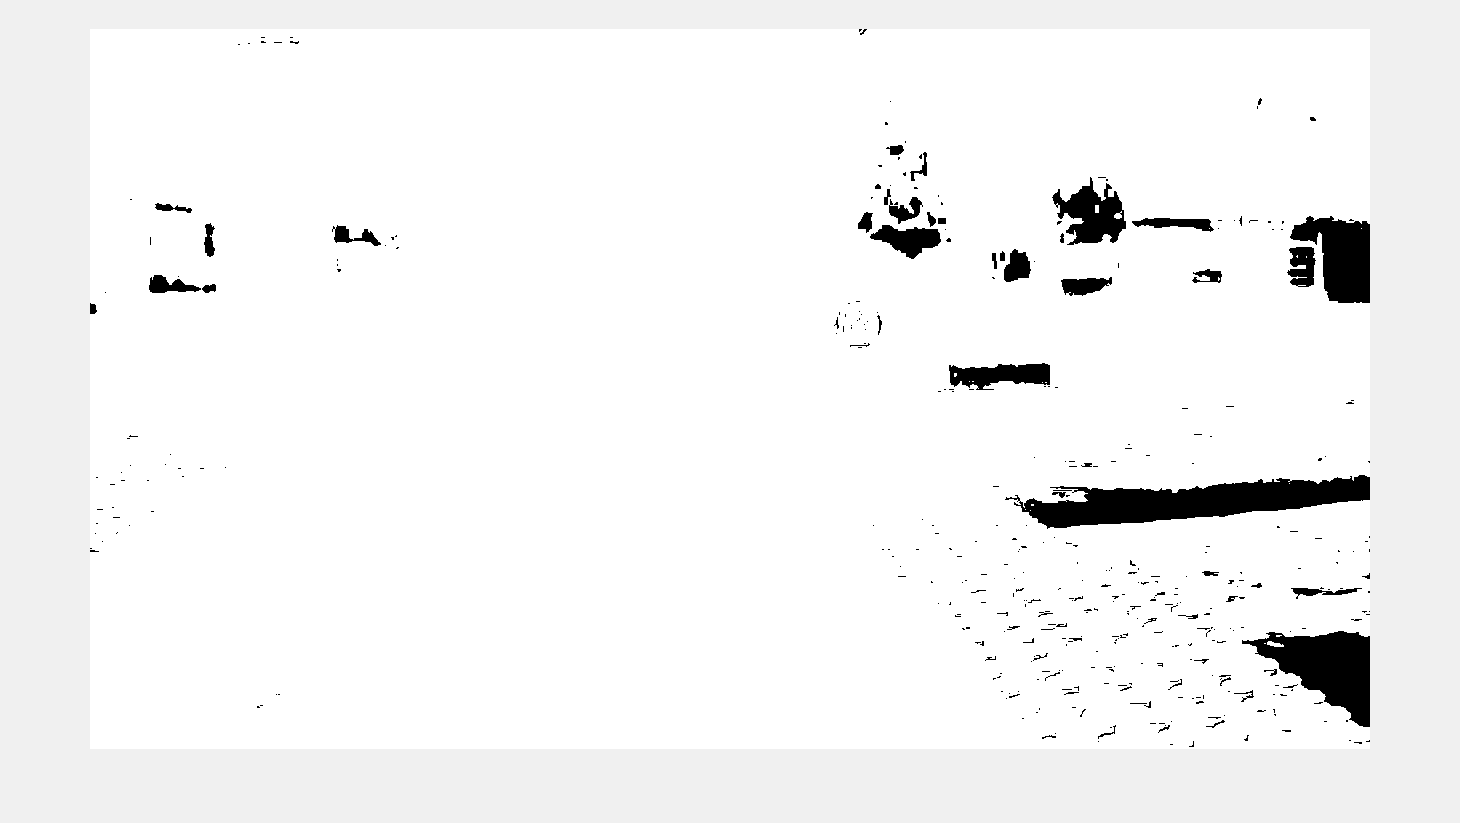


% Grauwert auswählen
% [x, y, val] = impixel;
% disp(['Grauwert an (', num2str(x), ',', num2str(y), '): ', num2str(val)]);

% Schwellwert in Grauwerten (0–255)
T = 45;
BW = grayImage > T;
imshow(BW);

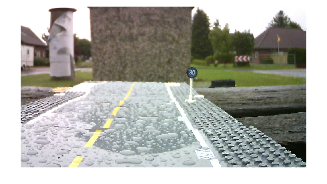

figure; 
imshow(I);

% eintragen der Bilddatei in excel
% writematrix(string(Pfadschild), filename, 'WriteMode', 'append');
[centers, radii] = imfindcircles(BW, [20 , 200], 'ObjectPolarity','bright','Sensitivity', 0.90 )


centers =

     []


radii =

     []



viscircles(centers, radii,'EdgeColor','r');